clear; clc;

%% Initial conditions at t=0
CA_init = 10;    % mol/m^3
CB_init = 18;    % mol/m^3
CC_init = 0;     % mol/m^3
T_init = 343;     % K
y0 = [CA_init; CB_init; CC_init; T_init];

%% Set constant Tj and T0
Tj = 343;        % K
T0 = 343;        % K

%% Time span
tspan = [0 600];  % seconds (10 minutes)

%% ODE system
odefun = @(t, y) solve_CSTR_ODE(t, y, T0, Tj);


tic;
[t1, y1] = ode45(odefun, tspan, y0);
time_ode45 = toc

time_ode45 = 0.0056


tic;
[t2, y2] = ode15s(odefun, tspan, y0);
time_ode15s = toc

time_ode15s = 0.0042


tic;
[t3, y3] = ode23s(odefun, tspan, y0);
time_ode23s = toc

time_ode23s = 0.0031

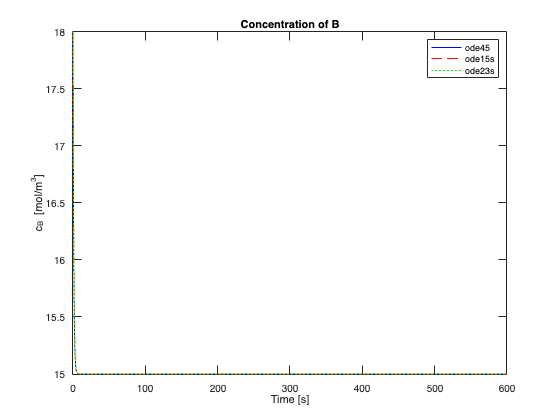

plot(t1, y1(:,2), 'b', t2, y2(:,2), 'r--', t3, y3(:,2), 'g:');
title('Concentration of B');
xlabel('Time [s]'); ylabel('c_B [mol/m^3]');
legend('ode45', 'ode15s', 'ode23s');

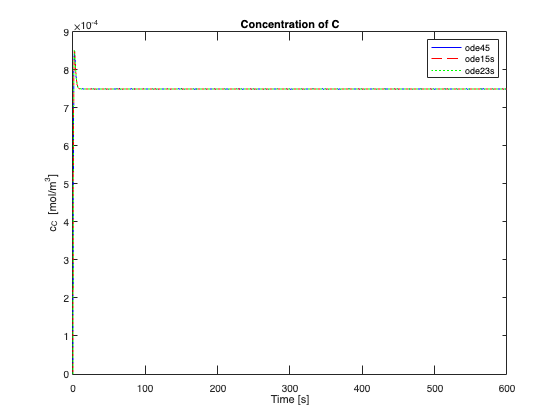

plot(t1, y1(:,3), 'b', t2, y2(:,3), 'r--', t3, y3(:,3), 'g:');
title('Concentration of C');
xlabel('Time [s]'); ylabel('c_C [mol/m^3]');
legend('ode45', 'ode15s', 'ode23s');

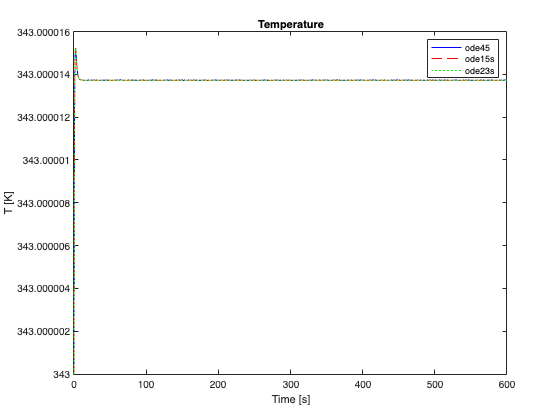

plot(t1, y1(:,4), 'b', t2, y2(:,4), 'r--', t3, y3(:,4), 'g:');
title('Temperature');
xlabel('Time [s]'); ylabel('T [K]');
legend('ode45', 'ode15s', 'ode23s');
legend('ode45', 'ode15s', 'ode23s');

## **sensitivity analysis**

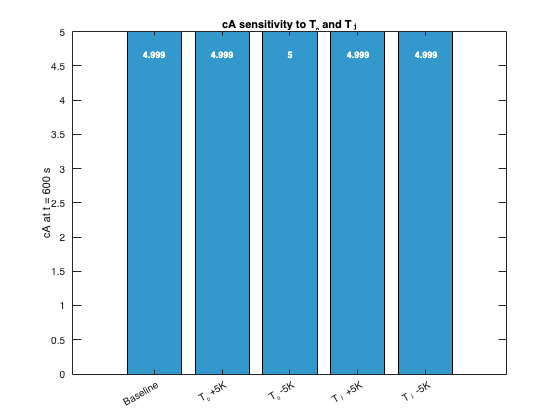

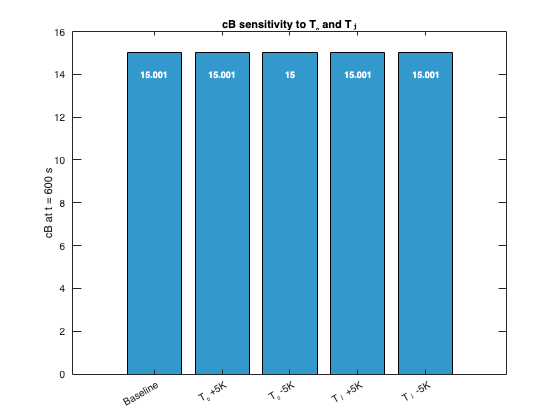

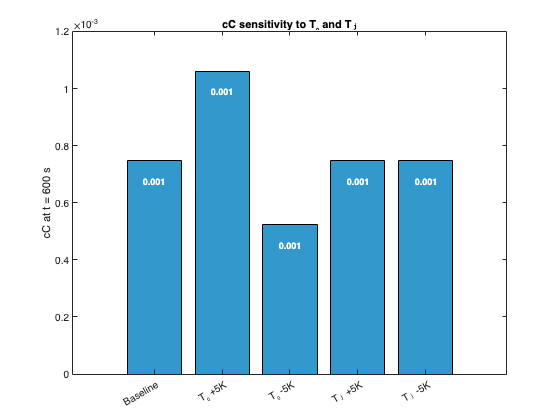

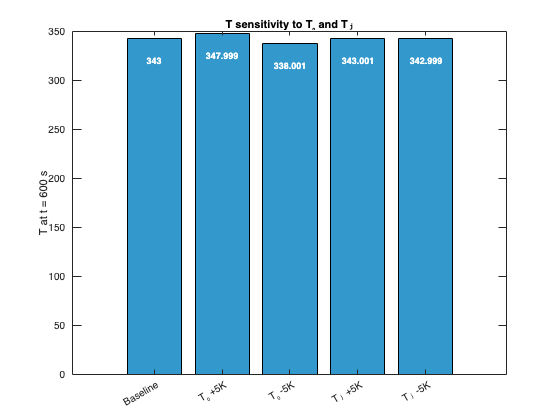

%% 5 scenarios: [T0, Tj]
T0_values = [343, 348, 338, 343, 343];
Tj_values = [343, 343, 343, 348, 338];

labels = [
    "Baseline";
    "T₀ +5K";
    "T₀ -5K";
    "Tⱼ +5K";
    "Tⱼ -5K"
];

%% Run simulations and store final results
results = zeros(5, 4);  % Each row: [cA, cB, cC, T]

for i = 1:5
    T0 = T0_values(i);
    Tj = Tj_values(i);

    odefun = @(t, y) solve_CSTR_ODE(t, y, T0, Tj);

    [t, y] = ode45(odefun, tspan, y0);
    results(i, :) = y(end, :);  % Save final values
end

%% Plotting with value labels
vars = {'cA', 'cB', 'cC', 'T'};
for k = 1:4
    figure;
    b = bar(results(:,k), 'FaceColor', [0.2 0.6 0.8]);
    set(gca, 'XTickLabel', labels, 'XTickLabelRotation', 30);
    ylabel([vars{k} ' at t = 600 s']);
    title([vars{k} ' sensitivity to T₀ and Tⱼ']);

    % Add value labels inside bars
    xtips = b.XEndPoints;
    ytips = b.YEndPoints;
    y_data = b.YData;
    labels_num = string(round(y_data, 3));

    % Offset downward inside the bar (e.g. 5% of value)
    for i = 1:length(xtips)
        text(xtips(i), ytips(i) - 0.05 * max(y_data), labels_num(i), ...
            'HorizontalAlignment','center', 'VerticalAlignment','top', ...
            'Color','w', 'FontSize',9, 'FontWeight','bold');
    end
end